# Численное решение задачи Коши для обыкновенного дифференциального уравнения первого порядка. Вариант 11.

## Получение таблицы значений решения задачи Коши

Воспользуемся встроенными методами языка Matlab

Определим шаг

h = 0.1

h = 0.1000

Определим вектор x

x0=0

x0 = 0

xn = 1

xn = 1

x=x0:h:xn;
y0 = 0

y0 = 0

[xacc,y_math] = ode113(@(x,y) (0.6-y^2)*cos(x)+0.2*y,x,y0)

xacc =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


y_math =          0
    0.0604
    0.1207
    0.1796
    0.2360
    0.2890
    0.3380
    0.3826
    0.4227
    0.4583


## Метод Эйлера

### С шагом h

#### Алгоритм

Для поиска решения применим формулу $y_{m+1} = y_{m}+hf(x_m,y_m), m=0,\dots,N-1$

#### Реализация

Реализация алгоритма находится в функции Euler.m

#### Результат работы

y_Euler=Euler(xacc(xacc<=0.5),y0,h)

y_Euler =          0
    0.0600
    0.1205
    0.1803
    0.2382
    0.2930


### С шагом $\frac{h}{2}$

#### Алгоритм

Для поиска решения применим формулы 


$$\hat y_{m+1} = y_{m}+hf(x_m,y_m)$$



$$\ y_{m+1} = y_{m} + \frac{h}{2}(f(x_m,y_m)+f(x_{m+1},\hat y_{m+1})), m=0,\dots,N-1$$


#### Реализация

Реализация алгоритма находится в функции advancedEuler.m

#### Результат работы

y_adv_Euler = advancedEuler(xacc(xacc<=0.5),y0,h)

y_adv_Euler =          0
    0.0603
    0.1204
    0.1792
    0.2356
    0.2885


### Уточнение по Ричардсону

Найдем главный член погрешности

s=2;
Rm = (y_adv_Euler - y_Euler)./(2^s-1)

Rm =          0
    0.0001
   -0.0000
   -0.0004
   -0.0009
   -0.0015


Уточним решение

y_rev=y_adv_Euler + Rm

y_rev =          0
    0.0604
    0.1204
    0.1789
    0.2347
    0.2871


## Построение графиков таблично заданных функций

Построим графики таблично заданных функций в одних осях координат

labels = {'Точное значение', 'Метод Эйлера', 'Усовершенствованный метод Эйлера', 'Уточненное по Ричардсону решение'}

labels = 1×4 cell array
    {'Точное значение'}    {'Метод Эйлера'}    {'Усовершенствованный метод Эйлера'}    {'Уточненное по Ричардсону решение'}



acc_plot = plot(xacc(xacc<=0.5),y_math(1:6))

acc_plot =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1000 0.2000 0.3000 0.4000 0.5000]
              YData: [0 0.0604 0.1207 0.1796 0.2360 0.2890]
              ZData: [1×0 double]

  Show all properties



hold on 
euler_plot=plot(xacc(xacc<=0.5),y_Euler)

euler_plot =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1000 0.2000 0.3000 0.4000 0.5000]
              YData: [0 0.0600 0.1205 0.1803 0.2382 0.2930]
              ZData: [1×0 double]

  Show all properties


adv_euler_plot=plot(xacc(xacc<=0.5),y_adv_Euler)

adv_euler_plot =   Line with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1000 0.2000 0.3000 0.4000 0.5000]
              YData: [0 0.0603 0.1204 0.1792 0.2356 0.2885]
              ZData: [1×0 double]

  Show all properties


richardson_plot=plot(xacc(xacc<=0.5),y_rev)

richardson_plot =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.1000 0.2000 0.3000 0.4000 0.5000]
              YData: [0 0.0604 0.1204 0.1789 0.2347 0.2871]
              ZData: [1×0 double]

  Show all properties


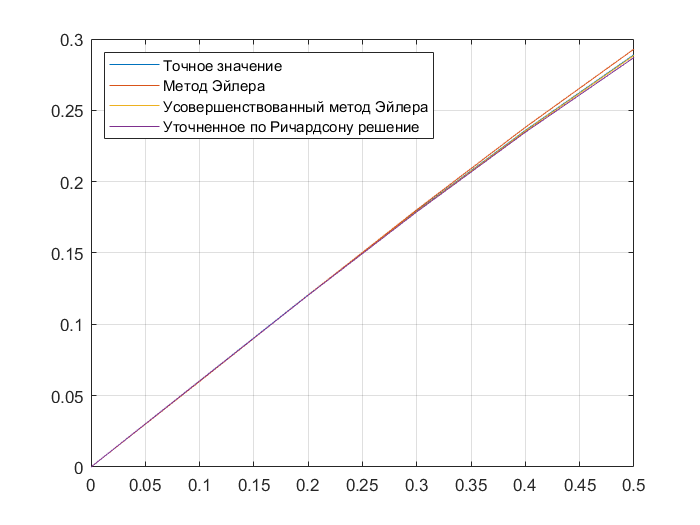

hold off

set(gca,'XGrid','on','YGrid','off')

xlim('auto')
ylim('auto')
grid on
legend(labels,'Location','northwest')

Y = [y_math(1:6),y_Euler,y_adv_Euler,y_rev]

Y =          0         0         0         0
    0.0604    0.0600    0.0603    0.0604
    0.1207    0.1205    0.1204    0.1204
    0.1796    0.1803    0.1792    0.1789
    0.2360    0.2382    0.2356    0.2347
    0.2890    0.2930    0.2885    0.2871


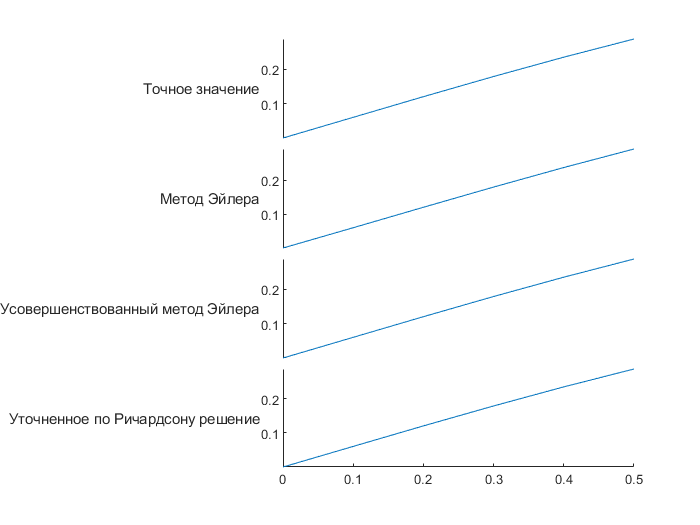

stackedplot(xacc(1:6),Y,'DisplayLabels',labels)

## Метод Рунге - Кутты четвертого порядка

### Алгоритм

Расчетные формулы метода:


$$y_{m+1} = y_m + \frac{1}{6}(k_1+2k_2+2k_3+k_4)$$



$$k_1 = hf(x_m,y_m)$$



$$k_2 = hf(x_m+\frac{h}{2},y_m+\frac{k_1}{2})$$



$$k_3 = hf(x_m+\frac{h}{2},y_m+\frac{k_2}{2})$$



$$k_4 = hf(x_m+h,y_m+k_3), m = 0,\dots,N-1$$


### Реализация

Реализация алгоритма находится в функции rungeCutt.m

### Результат работы

x_RK = transpose(0:h:1)

x_RK =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


y_RK = rungeCutt(x_RK,y0,h)

y_RK =          0
    0.0604
    0.1207
    0.1796
    0.2360
    0.2890
    0.3380
    0.3826
    0.4227
    0.4583


## Экстраполяционный метод Адамса

### Алгоритм

Расчетная формула имеет следующий вид:


$$y_{m+1}=y_m + \sum\limits_{j=0}^kb_{kj}q_{m-j}$$
  

где $b_{kj} = \frac{(-1)^j}{j!(k-j)!} \int\limits_0^1 \frac{t(t+1)\dots (t+k)}{t+j}dt, j=0,\dots,k$ , $q_{m-j} = hf(x_{m-j},y_{m-j})$

В нашем случае k = 4. В качестве первых k приближений используем значения y, полученные ранее методом Рунге - Кутты.

### Реализация

Реализация алгоритма описана в функции AdamsIn.m

### Результат работы

y_Ad_ex = adamsEx(x_RK,y_RK(1:5),h)

y_Ad_ex =          0
    0.0604
    0.1207
    0.1796
    0.2360
    0.2890
    0.3380
    0.3827
    0.4227
    0.4583


## Интерполяционный метод Адамса

### Алгоритм

В качестве начального приближения $y^{(0)}_{m+1}$ возьмем $y_{m+1}$, полученный с помощью экстраполяционного метода Адамса. Будем применять формулу


$$y^{(k+1)}_{m+1}=y^{(k)}_m + \sum\limits_{j=-1}^{k-1}b_{kj}^*q^{(k)}_{m-j}$$
  

где $b_{kj}^* = \frac{(-1)^{j+1}}{(j+1)!(k-j-1)!} \int\limits_0^1 \frac{(t-1)t\dots (t+k-1)}{t+j}dt, j=-1,\dots,k-1$ , $q^{(k)}_{m-j} = hf(x^{(k)}_{m-j},y^{(k)}_{m-j})$,

пока не будет выполнено условие $|y^{(k+1)}-y^{(k)}|<\epsilon$

### Реализация

Реализация алгоритма находится в функции adamsIn.m

### Результат работы

y_Ad_in = adamsIn(x_RK,y_Ad_ex,h)

y_Ad_in =          0
    0.0604
    0.1207
    0.1796
    0.2360
    0.2890
    0.3380
    0.3826
    0.4227
    0.4583


## Таблица погрешностей

labels = {'Точное значение', 'Метод Рунге-Кутты', 'Экстраполяционный метод Адамса', 'Интерполяционный метод Адамса'}

labels = 1×4 cell array
    {'Точное значение'}    {'Метод Рунге-Кутты'}    {'Экстраполяционный метод Адамса'}    {'Интерполяционный метод Адамса'}


errTable = table(y_math, y_math - y_RK,y_math - y_Ad_ex,y_math - y_Ad_in,'VariableNames',labels)

errTable = 11×4 table
    Точное значение    Метод Рунге-Кутты    Экстраполяционный метод Адамса    Интерполяционный метод Адамса
    _______________    _________________    ______________________________    _____________________________

              0                     0                          0                                 0         
       0.060382             1.786e-08                  1.786e-08                         1.786e-08         
        0.12066            1.5591e-08                 1.5591e-08                        1.5591e-08         
        0.17956           -5.6264e-08                -5.6264e-08                       -5.6264e-08         
        0.23598           -2.0391e-07                -2.0391e-07                       -2.0391e-07         
        0.28901           -3.5626e-07                -1.0832e-05                     